clear all;
filelist = [ "data_21-Mar-2025_10 motor1 19 to 31 rads.mat" ,
    "data_21-Mar-2025_10deazone mot1 pos.mat" , 
    "data_21-Mar-2025_20 deadzone mot1 neg.mat" , 
    "data_21-Mar-2025_20 motor1 1v.mat" ,
    "data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"]

filelist = 5×1 string array
    "data_21-Mar-2025_10 motor1 19 to 31 rads.mat"
    "data_21-Mar-2025_10deazone mot1 pos.mat"
    "data_21-Mar-2025_20 deadzone mot1 neg.mat"
    "data_21-Mar-2025_20 motor1 1v.mat"
    "data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"



% good : 1 4 5
exp_id = 5;
file = "lab3/data/motor1/" + filelist(exp_id)

file = "lab3/data/motor1/data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"

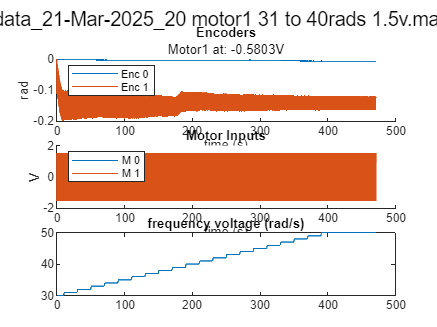

load(file,"data");
smartPlotEncVoltage(data,filelist(exp_id),false);


fs=500;
ts = 1/fs;


## Divide time to see what frequencies happen at which time:

motorID = 1;

voltages_A = [1 0 0 1 1.5];
voltage_A = voltages_A(exp_id);
time = data(1,:);
y = data(2+motorID,:)*pi/2048;
u = data(4+motorID,:);
% sweepanalysis assumes that the u has Amplitude 1
om = data(6,:);


slices = sliceTimeSeries(time,om);


% wrong_exp = [ 0 5.5 13 17.5 18 20];


maskOpts = detectImportOptions("lab3/data/motor1/experiment_mask_"+exp_id+".csv");
mask = readtable("lab3/data/motor1/experiment_mask_"+exp_id+".csv",maskOpts);



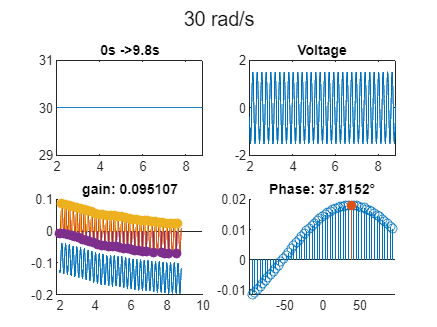

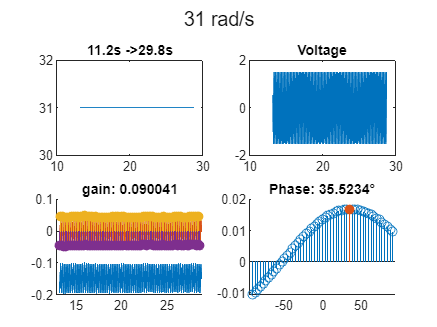

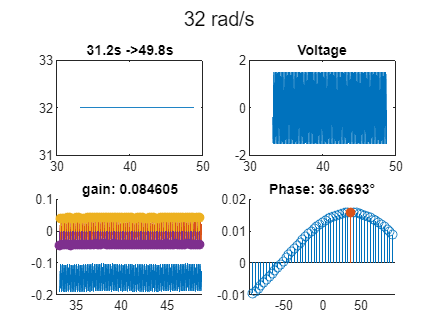

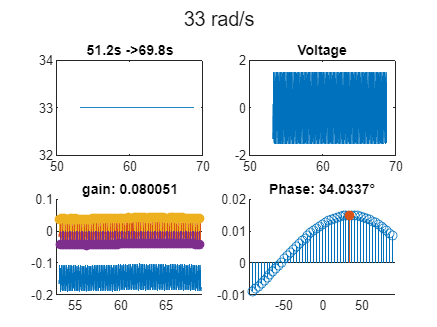

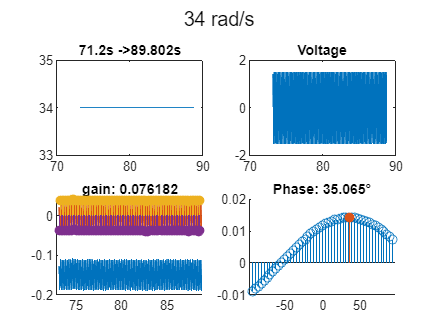

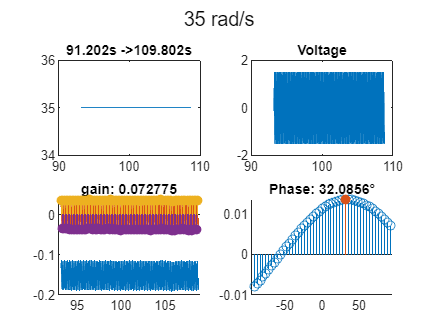

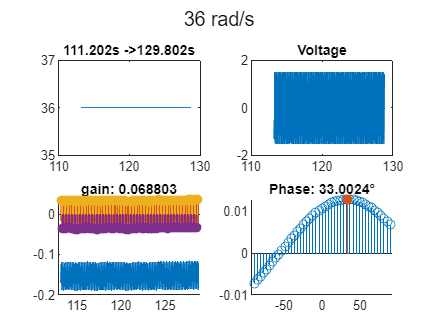

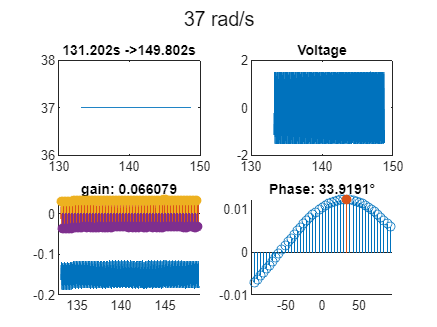

% for i = 2:2
for i = 1:size(slices,2)
    omega = slices{i}.f;
    % k = find(wrong_exp==omega);
if mask.enable(i) % it's one of the wrong experiments
    focus = slices{i};

    t_start_idx = time2index(focus.t_start+mask.t_start(i));
    t_end_idx = time2index(focus.t_end-mask.t_end(i));
   

    t_focus= time(t_start_idx:t_end_idx);
    om_focus= om(t_start_idx:t_end_idx);
    y_focus= y(t_start_idx:t_end_idx);
    u_focus= u(t_start_idx:t_end_idx);
    
    figure
    subplot(2,2,1)
        plot(t_focus,om_focus)
        title(focus.t_start + "s ->" + focus.t_end + "s")
    subplot(2,2,2)
        plot(t_focus,u_focus)
        title("Voltage")
    subplot(2,2,[3 4])
     [phase, gain, phase_del] = SweepAnalysis(t_focus,u_focus, y_focus, omega);
    slices{i}.phase = phase;
    slices{i}.gain = gain;
    slices{i}.phase_del = phase_del;
    sgtitle(omega + " rad/s")
else
    slices{i}.phase = NaN;
    slices{i}.gain = NaN;
    slices{i}.phase_del = NaN;
end
end

[freqs,phases, gains, phase_dels] = flatten(slices);

gains = gains/voltage_A

gains =     0.0634    0.0600    0.0564    0.0534    0.0508    0.0485    0.0459    0.0441    0.0420    0.0406    0.0385    0.0360    0.0348    0.0341    0.0337    0.0319    0.0310    0.0299    0.0288    0.0277    0.0267


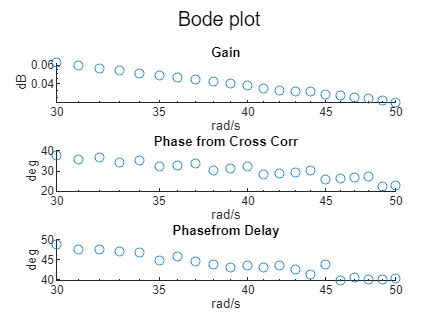


figure
sgtitle("Bode plot")
subplot(3,1,1)
scatter(freqs,gains)
yscale("log")
xscale("log")
title("Gain")
xlabel("rad/s")
ylabel("dB")

subplot(3,1,2)
scatter(freqs,rad2deg(phases))
xscale("log")
% ylim([0 90])
title("Phase from Cross Corr")
xlabel("rad/s")
ylabel("deg")


subplot(3,1,3)
scatter(freqs,rad2deg(phase_dels))
xscale("log")
% ylim([0 90])
title("Phasefrom Delay")
xlabel("rad/s")
ylabel("deg")


%

% Save file
tableofData = [freqs; phases; gains]'

tableofData =    30.0000    0.6600    0.0634
   31.0000    0.6200    0.0600
   32.0000    0.6400    0.0564
   33.0000    0.5940    0.0534
   34.0000    0.6120    0.0508
   35.0000    0.5600    0.0485
   36.0000    0.5760    0.0459
   37.0000    0.5920    0.0441
   38.0000    0.5320    0.0420
   39.0000    0.5460    0.0406



writematrix(tableofData, "lab3/data/motor1/expm1", FileType="spreadsheet",WriteMode='append')



function idx = time2index(time)
    idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
        freqs(i) = slices{i}.f;
        phases(i) = slices{i}.phase;
        gain(i) = slices{i}.gain;
        phase_dels(i) = slices{i}.phase_del;
    end

end

